# **Análise e Modelagem de Sistemas Dinâmicos - 2023/2**

## Nome: Thamya Vieira Hashimoto Donadia 

## Data limite para entrega: 27/11/2023

### A entrega deverá ser feita pelo Google ClassRoom

# Trabalho 3 - Resposta no Tempo, Estabilidade e Sistemas Discretos

I = 17;  % Seu número I
init_t3(I);  % Define as variaveis do modelo 1
datetime('now')

ans = datetime
   01-Dec-2023 18:41:29


**Funções úteis do Matlab:** tf, tfdata, step, RespConfig, minreal, figure, plot, hold, grid, stairs, title, xlabel, ylabel, legend, sprintf, fprintf, ss, d2c, roots, sort, real, imag, abs, sqrt, poly, length, feedback, initial, tf2ss, cart2pol, eig, vpa, eval.

## Análise da Resposta no Tempo Contínuo

A Função de Transferência baixo foi designada em função do seu valor de I.

G

G =
 
               4913
  ------------------------------
  s^3 + 238 s^2 + 7225 s + 58956
 
Continuous-time transfer function.
Model Properties


### 1.1 Plote a resposta ao degrau de $G\left(s\right)$ para um degrau de amplitude $U$.

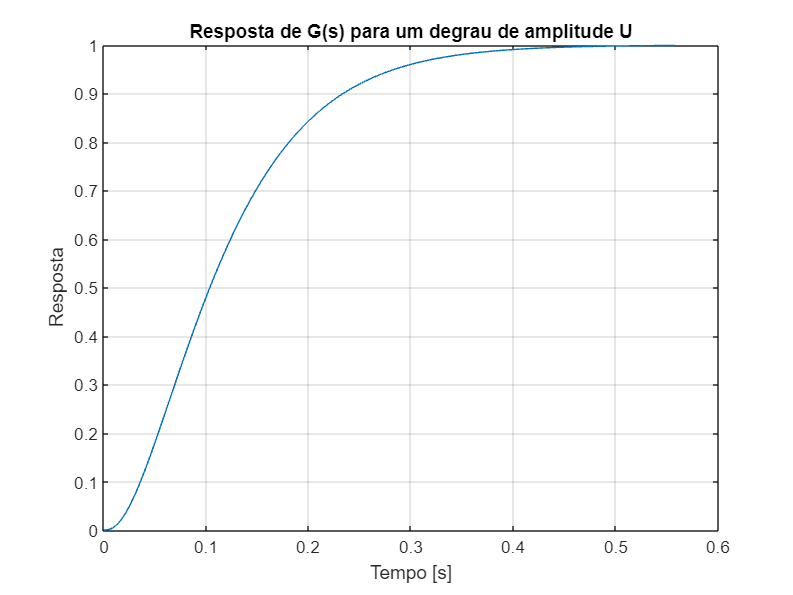

% Configuração para modificar a amplitude do degrau
config = RespConfig('Amplitude', U);

% Plot da resposta ao degrau de amplitude U
[y1, t1] = step(G, config);
figure; plot(t1, y1), 

title("Resposta de G(s) para um degrau de amplitude U");
xlabel("Tempo [s]"); ylabel("Resposta"); grid on

### 1.2 Encontre a função $Q\left(s\right)$ de 1ª ou de 2ª ordem (conforme o caso), cuja resposta ao degrau se aproxime a resposta ao degrau de $G\left(s\right)$.

A partir da resposta de $G\left(s\right)$ para um degrau de amplitude $U$, é possível observar que o formato do gráfico se assemelha à resposta de um sistema de 1° ordem ao degrau unitário. Nesse caso, temos que o sistema $Q\left(s\right)$ pode ser representado, de forma geral, como $Q\left(s\right)=\frac{K}{\tau s+1}$, em que $\tau$ é a constante de tempo do sistema, e $K$, o ganho estacionário.

Considere $G\left(s\right)=\frac{F\left(s\right)}{U\left(s\right)}\Rightarrow F\left(s\right)=G\left(s\right)U\left(s\right)$ e $u\left(t\right)=12\Rightarrow U\left(s\right)=\frac{12}{s}$ . Assim, aplicando o Teorema do Valor Final, temos: 


$$\begin{array}{l}
\lim_{t\to \infty } f\left(t\right)=\lim_{s\to 0} \;\mathrm{sG}\left(s\right)U\left(s\right)=K\Rightarrow K=\lim_{s\to 0} \;s\left(\frac{4913}{s^3 +238s^2 +7225s+58956}\right)\left(\frac{12}{s}\right)\Rightarrow \\
\\
\Rightarrow K=\;\lim_{s\to 0} \;\left(\frac{58956}{s^3 +238s^2 +7225s+58956}\right)=\frac{58956}{58956}=1\;
\end{array}$$


Para determinar a constante de tempo, temos que $f\left(\tau \right)=0,63K$. 

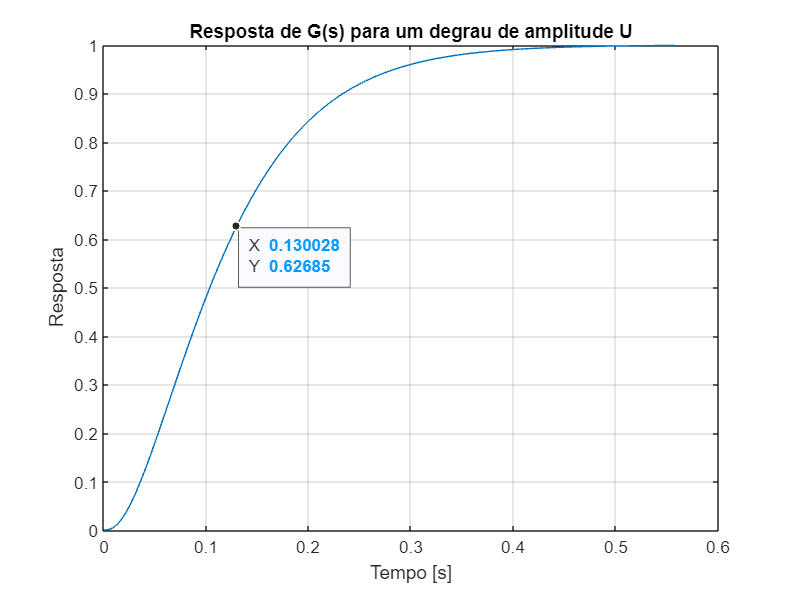

% Plot novo da resposta ao degrau, marcando o ponto da constante de tempo
figure; grafico_1 = plot(t1, y1);

title("Resposta de G(s) para um degrau de amplitude U");
xlabel("Tempo [s]"); ylabel("Resposta"); grid on

% Valor de y1, tal que t1 = constante de tempo
valor_y1 = 0.63; % Tomando k = 1

% Para encontrar o índice do valor mais próximo em y1
indice = find(abs(y1-valor_y1) == min(abs(y1 - valor_y1)));

% Para obter o valor correspondente em t1
valor_t1 = t1(indice);

% Marcando o ponto desejado no gráfico
datatip(grafico_1, valor_t1, valor_y1, "Location", "southeast");

Dessa forma, temos que $\tau =0\ldotp 13$. Assim, reescrevendo a função $Q\left(s\right)$, obtemos: 

$Q\left(s\right)=\frac{K}{\tau s+1}\Rightarrow Q\left(s\right)=\frac{1}{0\ldotp 13s+1}$.

### 1.3 Compare, no mesmo gráfico, a resposta ao degrau de $Q\left(s\right)$ com a resposta ao degrau de $G\left(s\right)$ para um degrau de amplitude $U$. Explique a resposta.

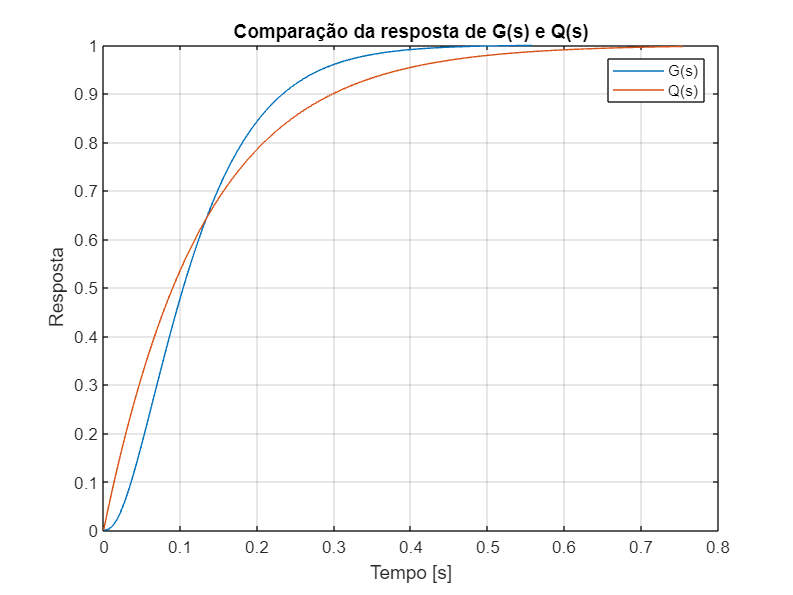

% Resposta ao degrau de Q(s)
s = tf('s'); Q = 1/(0.13*s + 1);
[y2, t2] = step(Q);

% Plot das duas respostas em um mesmo gráfico
figure; plot(t1, y1)
hold on, plot(t2, y2)

grid on, legend("G(s)", "Q(s)");
title("Comparação da resposta de G(s) e Q(s)");
xlabel("Tempo [s]"); ylabel("Resposta"); 

A partir do gráfico de comparação, é possível observar que as funções $Q\left(s\right)\;$e $G\left(s\right)\;$apresentam respostas aproximadas quando submetidas a um degrau unitário e de amplitude $U$, respectivamente. No entanto, há algumas discrepâncias, especialmente no tempo de estabilização e no início da curva (nas proximidades da origem).  

### 1.4 A partir da equação de $Q\left(s\right)$ e de medições feitas diretamente no gráfico da resposta ao degrau de $Q\left(s\right)$, para um degrau de amplitude $U$, informe os valores de $\zeta$, $\omega_n$, $\textrm{MP}$, $t_p$, $t_r$ e $t_s \left(5%\right)$. (Mostre com *Data Tips* sempre que for possível marcar os valores no gráfico)

Como $Q\left(s\right)$ caracteriza um sistema de 1° ordem, ele não apresenta os valores de $\zeta$,$\omega_n$,$\textrm{MP}$ e $t_p$. Para o tempo de subida $\left(t_r \right)$ e de estabilização a 5% $\left(t_{\textrm{s5}} \right)$, temos: 

$t_r \approx 2\ldotp 2\tau =2\ldotp 2*0\ldotp 13=0\ldotp 286s$ e $t_{\textrm{s5}} \approx 3\tau =3*0\ldotp 13=0\ldotp 39s$

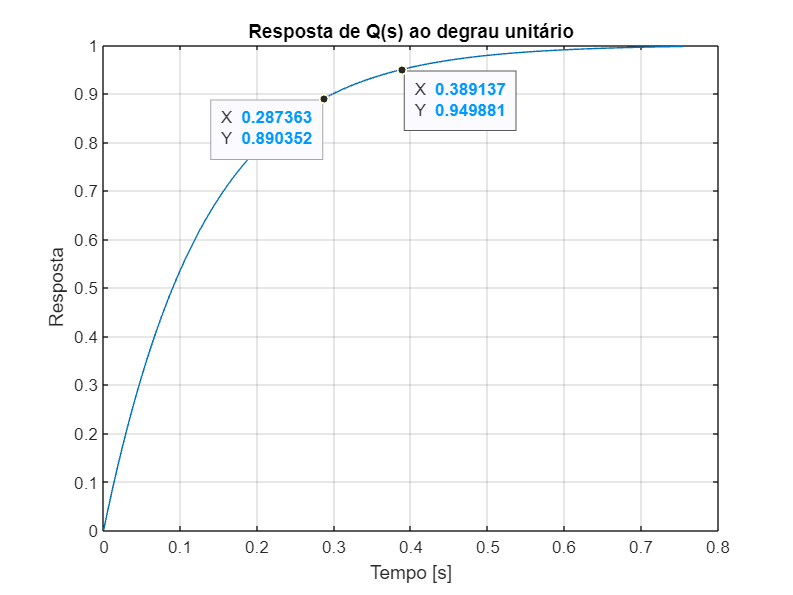

% Plot novo da resposta ao degray de Q(s) 
figure; grafico_2 = plot(t2, y2); grid on;
title("Resposta de Q(s) ao degrau unitário");
xlabel("Tempo [s]"); ylabel("Resposta"); 

% Para encontrar o valor de y2, tal que t2 = tempo de subida
valor_tr = 0.286;
indice_tr = find(abs(t2 - valor_tr) == min(abs(t2 - valor_tr)));
valor_y2_tr = y2(indice_tr);

datatip(grafico_2, valor_tr, valor_y2_tr, "Location", "southwest");

% Para encontrar o valor de y2, tal que t2 = tempo de estabilização
valor_ts = 0.39;
indice_ts = find(abs(t2-valor_ts) == min(abs(t2 - valor_ts)));
valor_y2_ts = y2(indice_ts);

datatip(grafico_2, valor_ts, valor_y2_ts, "Location", "southeast");

### 1.5 Feche a malha do processo $G\left(s\right)$ com uma realimentação de ganho $K$. Obtenha a faixa de valores de $K$ em que o sistema é estável.

A partir de uma malha do processo $G\left(s\right)$, com realimentação de ganho $K$, temos a seguinte função de transferência do novo sistema: 


$$\begin{array}{l}
H\left(s\right)=\frac{G\left(s\right)}{1+G\left(s\right)K}=\frac{4913}{s^3 +238s^2 +7225s+58956}*\frac{1}{1+\left(\frac{4913K}{s^3 +238s^2 +7225s+58956}\right)}\Rightarrow \\
\\
\Rightarrow H\left(s\right)=\;\frac{4913}{s^3 +238s^2 +7225s+\left(58956+4913K\right)}\;
\end{array}$$


Das condições do arranjo de Routh temos: $\left(58956+4913K\right)>0\Rightarrow K>-12$. Assim, construindo o arranjo de Routh: 

$\begin{array}{l}
s^{3\;} \left|\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;7225\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\;\right.\\
s^2 \;|\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;238\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(58956+4913K\right)\;\;\;0\\
---------------------\\
s^1 \;|\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;a_{1\;} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\\
s^0 \;\;|\;\;\left(58956+4913K\right)\;\;\;\;\;\;\;\;\;\;\;\;0
\end{array}$ , 

com $a_1 =\frac{\left(\left(238*7225\right)-\;\left(58956+4913K\right)\right)}{238}=\frac{\left(1660594-4913K\right)}{238}$

Para que o sistema seja estável, não pode ter troca de sinais e elementos nulos na primeira coluna. Dessa forma, das condições dos valores de $K$, temos: 


$$\left(58956+4913K\right)>0\;e\;a_1 >0\Rightarrow K>-12\;e\;\left(1660594-4913K\right)>0\Rightarrow K>-12\;e\;K<338\Rightarrow -12<K<338$$


## Análise da Resposta no Tempo Discreto

A Função de Transferência baixo foi designada em função do seu valor de I.

Dz

Dz =
 
  0.007413 z^2 + 0.01483 z + 0.007413
  -----------------------------------
        z^2 - 0.807 z + 0.1628
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


### 2.1 Obtenha o modelo equivalente contínuo $D_t \left(s\right)$ de $D\left(z\right)$ usando a transformação bilinear para $T_s =50\left\lbrack \textrm{ms}\right\rbrack$.

Para a transformação bilinear, por meio da função "d2c",  temos 

Dt = d2c(Dz, "tustin")

Dt =
 
       24.08
  ----------------
  s^2 + 34 s + 289
 
Continuous-time transfer function.
Model Properties


### 2.2 Obtenha o modelo equivalente contínuo $D_{\textrm{zoh}} \left(s\right)$ de $D\left(z\right)$ usando ZOH para $T_s =50\left\lbrack \textrm{ms}\right\rbrack$.

Para a transformação usando ZOH, por meio da função "d2c", temos

D_zoh = d2c(Dz, "zoh")

D_zoh =
 
  0.007413 s^2 + 0.4338 s + 27.46
  -------------------------------
       s^2 + 36.3 s + 329.5
 
Continuous-time transfer function.
Model Properties


### 2.3 Compare a resposta ao degrau unitário de $D_z \left(z\right)$, $D_{\textrm{zoh}} \left(s\right)$ e $D_t \left(s\right)$. Explique o resultado.

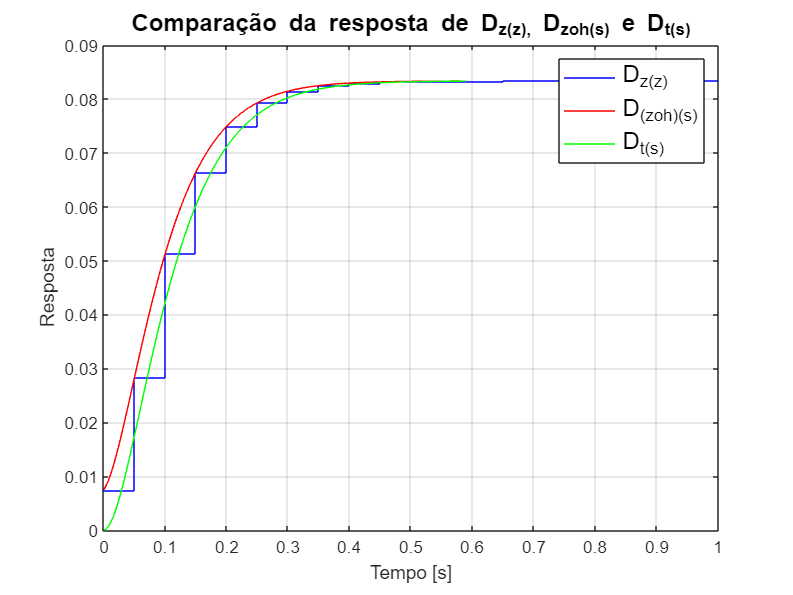

% Obtendo as respostas ao degrau unitário das funções 
[y3, t3] = step(Dz);
[y4, t4] = step(D_zoh);
[y5, t5] = step(Dt);

% Criando os plots das respostas 
figure; stairs(t3, y3, "Color", "blue"), hold on;
plot(t4, y4, "Color", "red"), hold on;
plot(t5, y5, "Color", "green"), hold off;

grid on, legend({'D_z(z)', 'D_(zoh)(s)', 'D_t(s)'}, "FontSize", 14);
title("Comparação da resposta de D_z(z), D_zoh(s) e D_t(s)", "FontSize", 14);
xlabel("Tempo [s]"); ylabel("Resposta"); 

A partir do gráfico, é possível observar o comportamento do ZOH de segurar a ordem zero entre as amostras, o que implica que o sinal é mantido constante durante o intervalo de amostragem. Já no transformação bilinear, é possível verificar que o método mantém a estabilidade do sistema, neste caso, a tendência ao valor estacionário.  

### 2.4 Obtenha as matrizes do modelo no EE de $D_z \left(z\right)$.

% Montando o vetor de numerador e denonimador da função Dz(z)
[numerador, denominador, ts] = tfdata(Dz),

numerador = 1x1 cell array
    {[0.0074 0.0148 0.0074]}


denominador = 1x1 cell array
    {[1 -0.8070 0.1628]}


ts = 0.0500

% Obtendo o sistema em espaço de estados 
[A, B, C, D] = tf2ss(cell2mat(numerador), cell2mat(denominador))

A =     0.8070   -0.1628
    1.0000         0


B =      1
     0


C =     0.0208    0.0062


D = 0.0074

Assim, tomando o sistema em espaço de estados é dado por: 


$$\begin{array}{l}
q_{k+1} =\left\lbrack A\right\rbrack q_k +\left\lbrack B\right\rbrack u_k ;y_k =\left\lbrack C\right\rbrack q_{k\;} +\left\lbrack D\right\rbrack u_k \Rightarrow \\
\\
\Rightarrow q_{k+1} =\left\lbrack \begin{array}{cc}
0\ldotp 8070 & -0\ldotp 1628\\
1 & 0
\end{array}\right\rbrack q_k +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack u_k \;e\;y_k =\left\lbrack \begin{array}{cc}
0\ldotp 0208 & 0\ldotp 0062
\end{array}\right\rbrack q_k +\left\lbrack 0\ldotp 0074\right\rbrack u_k \;
\end{array}$$


### 2.5 Obtenha a matrix de transição de estados $\Phi[k] = A^k$ e use-a para obter a saída $y[k]$ do sistema para $\vec{q}_0$ com todos os elementos iguais a 1. Compare a resposta obtida com a produzida pela função "initial" do MATLAB. Considere $T_s =50\left\lbrack \textrm{ms}\right\rbrack$ e apresente o gráfico com tempo até três segundos.

Da matriz A, temos que seus autovalores são dados por 


$$\begin{array}{l}
\phi \;\left(\lambda \right)=\det \left(\lambda \mathit{\mathbf{I}}-\mathit{\mathbf{A}}\right)=0\Rightarrow \det \left\lbrack \begin{array}{cc}
\lambda -0\ldotp 8070 & 0\ldotp 1628\\
-1 & \lambda 
\end{array}\right\rbrack =0\Rightarrow \\
\\
\Rightarrow \frac{\left(5000\lambda^2 -4035\lambda +814\right)}{5000}=0\Rightarrow \lambda_1 =0\ldotp 407\;e\;\lambda_2 =0\ldotp 4
\end{array}$$


Assim, pelo Teorema de Cayley- Hamilton, temos


$$\lambda^k =p_o \left(k\right)+p_1 \left(k\right)\lambda \Rightarrow \left\lbrace \begin{array}{ll}
{\left(0\ldotp 407\right)}^k =p_o \left(k\right)+p_1 \left(k\right)0\ldotp 407 & \\
{\left(0\ldotp 4\right)}^k =p_o \left(k\right)+p_1 \left(k\right)0\ldotp 4 & 
\end{array}\right.\Rightarrow \left\lbrace \begin{array}{ll}
p_o \left(k\right)=\frac{1000}{7}\left\lbrack {\left(0\ldotp 407\right)}^k -{\left(0\ldotp 4\right)}^k \right\rbrack  & \\
p_1 \left(k\right)=\frac{407}{7}{\left(0\ldotp 4\right)}^k -\frac{400}{7}{\left(0\ldotp 407\right)}^k  & 
\end{array}\right.\;$$


Logo, 


$$\begin{array}{l}
{\mathit{\mathbf{A}}}^{k\;} =p_o \left(k\right)\mathit{\mathbf{I}}+p_1 \left(k\right)\mathit{\mathbf{A}}\Rightarrow {\mathit{\mathbf{A}}}^k =\left\lbrack \begin{array}{cc}
p_o \left(k\right)+0\ldotp 8070p_1 \left(k\right) & -0\ldotp 1628p_1 \left(k\right)\\
p_1 \left(k\right) & p_o \left(k\right)
\end{array}\right\rbrack \Rightarrow \\
\\
\Rightarrow {\mathit{\mathbf{A}}}^k =\;\left(\frac{1}{7}\right)\left\lbrack \begin{array}{cc}
677\ldotp 2{\left(0\ldotp 407\right)}^{\;k} -671\ldotp 551{\left(0\ldotp 4\right)}^{\;k} \; & 65\ldotp 12{\left(0\ldotp 407\right)}^k -66\ldotp 2596{\left(0\ldotp 4\right)}^k \\
407{\left(0\ldotp 4\right)}^k -400{\left(0\ldotp 407\right)}^k  & 1000{\left(0\ldotp 407\right)}^k -1000{\left(0\ldotp 4\right)}^k 
\end{array}\right\rbrack 
\end{array}$$


% Criando as variáveis simbólicas e o vetor de estados iniciais 
Ts = 0.05; z = tf('z', Ts); syms k; q0 = [1 ; 1]; 

% Montando a matriz de transição de estados
A_k = (1/7)*[(677.2*(0.407)^k - 671.551*(0.4)^k) (65.12*(0.407)^k - 66.2596*(0.4)^k);
               (407*(0.4)^k - 400*(0.407)^k)        (1000*(0.407)^k - 1000*(0.4)^k);]

$$A\_k = \left(\begin{array}{cc} \frac{3386\,{\left(\frac{407}{1000}\right)}^{k}}{35}-\frac{5907025065156805\,{\left(\frac{2}{5}\right)}^{k}}{61572651155456} & \frac{1628\,{\left(\frac{407}{1000}\right)}^{k}}{175}-\frac{2331302420857173\,{\left(\frac{2}{5}\right)}^{k}}{246290604621824}\\ \frac{407\,{\left(\frac{2}{5}\right)}^{k}}{7}-\frac{400\,{\left(\frac{407}{1000}\right)}^{k}}{7} & \frac{1000\,{\left(\frac{407}{1000}\right)}^{k}}{7}-\frac{1000\,{\left(\frac{2}{5}\right)}^{k}}{7} \end{array}\right)$$

resposta_homogenea = C * A_k * q0

$$resposta\_homogenea = \frac{17265830421818953881\,{\left(\frac{407}{1000}\right)}^{k}}{6305039478318694400}-\frac{96501957604590085334035498551327\,{\left(\frac{2}{5}\right)}^{k}}{35494216806390423241907689750528}$$

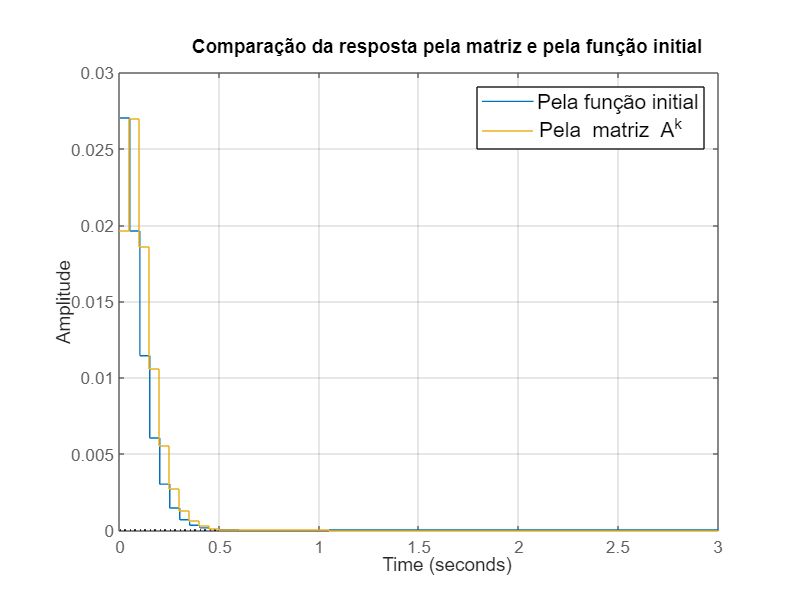

% Substituindo a variável simbólica 'k' por um range de valores
vetor_tempo = 0:Ts:3; vetor_k = 0:(length(vetor_tempo)-1);
yk1_homogenea = subs(resposta_homogenea, k, vetor_k);

% Obter a resposta homogênea pela função
sys = ss(A, B, C, D, Ts);

t_final = 3; % Para apresentar o gráfico com tempo até três segundos. 
figure; initial(sys, q0, t_final); hold on
stairs(vetor_tempo, yk1_homogenea), hold off, grid on

legend({"Pela função initial", "Pela matriz A^k"}, "FontSize", 12);
title("Comparação da resposta pela matriz e pela função initial");

A partir do plot dos dois gráficos, é possível observar que eles apresentam comportamentos parecidos a partir de uma condição inicial. As leves discrepâncias nas linhas podem ter ocorrido em função das aproximações realizadas nas contas. No entanto, de forma geral, o comportamento observado é esperado para uma resposta homogênea (natural), tomando a condição inicial $\vec{q_o }$.